# TestFile for Lab 4

clear; clc;

## 3.1


Fs = 8000;
nums = ['0', '1', '2', '3']

nums = '0123'

zeroMe = dtmfdial(nums, Fs);

fRow = 941

fCol = 1336

fRow = 697

fCol = 1209

fRow = 697

fCol = 1336

fRow = 697

fCol = 1477

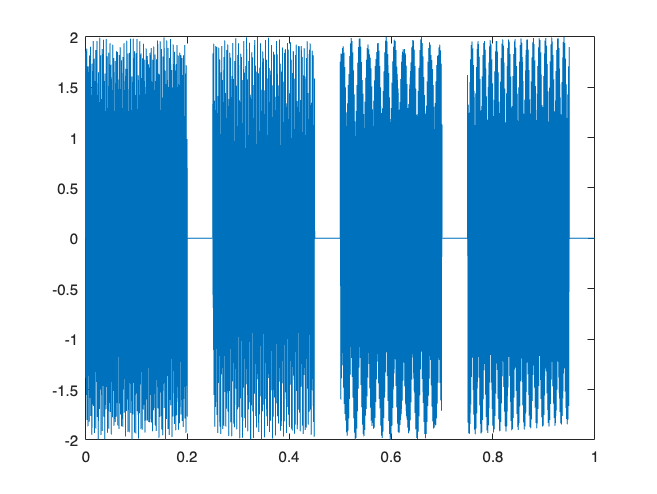

soundsc(zeroMe) % Cool!

t = 0:1/Fs:0.25 * length(nums) - 1/Fs; % Sampling values for sinusoids 0.20s long.

plot(t, zeroMe)

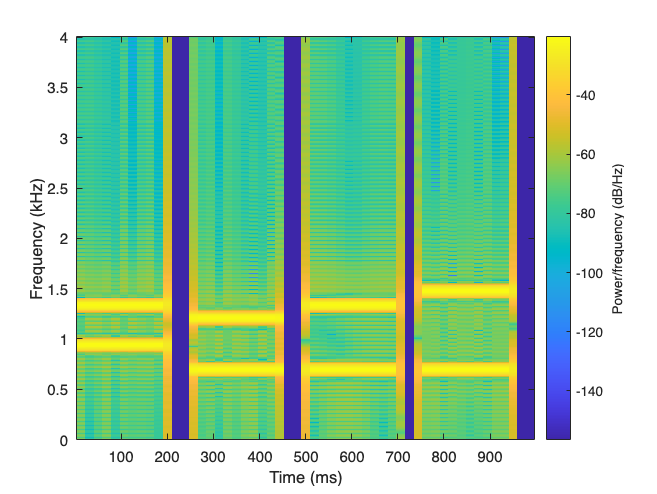


spectrogram(zeroMe,200,50,1000,Fs,'yaxis')

## 4.1

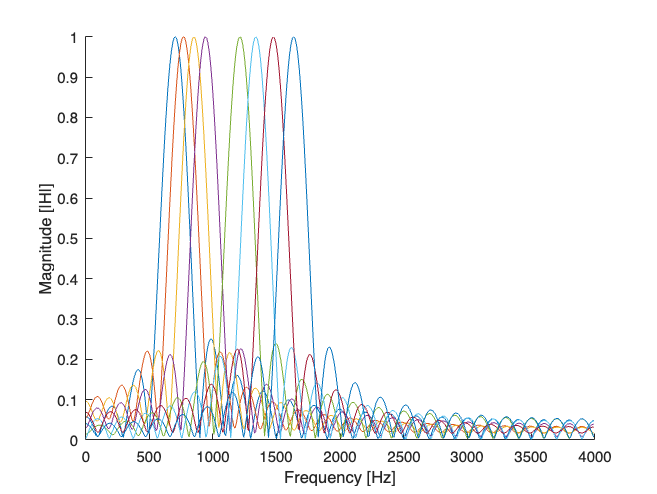

% Parts A & B
% Function is written below, we used the numerical method to scale the maximum magnitude of the frequency response of the filter to be 1.

% Part C
% Here we generate the frequency filer bank
Fb = [697, 770, 852, 941, 1209, 1336, 1477, 1633]; % Define Center Frequencies

% Part D
% Generate the bandpass filters with L= 40 and fs = 8000. Plot the magnitude of the frequency responses all together on one plot to
% determine if the passbands are narrow enough to distinguish between each frequency.
%
% They are not narrow enough to distinguish using the 0.707 threshold. Especially at lower frequencies values 697, 770, 852, 941 Hz since they are pretty close together.
Fs = 8000;
L = 40;

hh = dtmfdesign(Fb, L, Fs); % Generate the frequency filter bank
[H1, ~] = freqz(hh(:,1)); [H2, ~] = freqz(hh(:,2));
[H3, ~] = freqz(hh(:,3)); [H4, ~] = freqz(hh(:,4));
[H5, ~] = freqz(hh(:,5)); [H6, ~] = freqz(hh(:,6));
[H7, ~] = freqz(hh(:,7)); [H8, w] = freqz(hh(:,8));

f = w*Fs/(2*pi); % Denormalize the angular frequency so we can plot in Hz

figure
hold on
plot(f, abs(H1)); plot(f, abs(H2));
plot(f, abs(H3)); plot(f, abs(H4));
plot(f, abs(H5)); plot(f, abs(H6));
plot(f, abs(H7)); plot(f, abs(H8));
hold off
xlabel('Frequency [Hz]')
ylabel('Magnitude [|H|]')

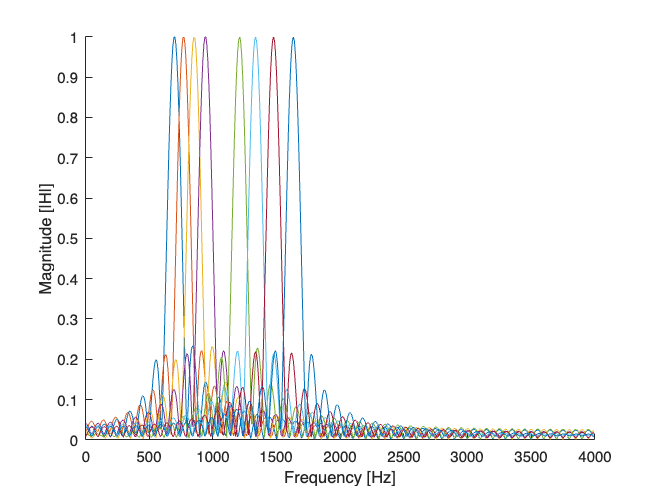


% Part E
% Generate the eight (scaled) bandpass filters with L= 80 and fs = 8000. Plot the magnitude of the frequency responses all together on one plot to
% determine if the passbands are narrow enough to distinguish between each frequency.
%
% By increasing the filter lengths, the passband is much narrower making it easier to distinguish between frequencies but still not enough for the 0.707 threshold.
Fs = 8000;
L = 80;

hh = dtmfdesign(Fb, L, Fs); % Generate the frequency filter bank
[H1, ~] = freqz(hh(:,1)); [H2, ~] = freqz(hh(:,2));
[H3, ~] = freqz(hh(:,3)); [H4, ~] = freqz(hh(:,4));
[H5, ~] = freqz(hh(:,5)); [H6, ~] = freqz(hh(:,6));
[H7, ~] = freqz(hh(:,7)); [H8, w] = freqz(hh(:,8));

f = w*Fs/(2*pi); % Denormalize the angular frequency so we can plot in Hz

figure
hold on
plot(f, abs(H1)); plot(f, abs(H2));
plot(f, abs(H3)); plot(f, abs(H4));
plot(f, abs(H5)); plot(f, abs(H6));
plot(f, abs(H7)); plot(f, abs(H8));
hold off
xlabel('Frequency [Hz]')
ylabel('Magnitude [|H|]')

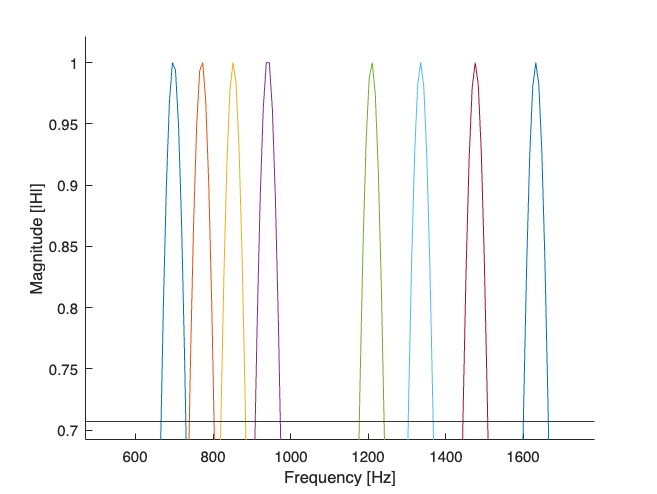



% Part F
% Generate the eight (scaled) bandpass filters with L= ? and fs = 8000. Plot the magnitude of the frequency responses all together on one plot to
% determine if the passbands are narrow enough to distinguish between each frequency.
%
% We chose L = 110 as the value which allows frequencies to be distinguishable. The frequency 'driving' the problem is the 697Hz frequency because of
% how close it it to the next value.
Fs = 8000;
L = 110; % This is a good value as it allows frequencies to be distinguished between each other. This allows the 1/sqrt(2) threshold to hold.

hh = dtmfdesign(Fb, L, Fs); % Generate the frequency filter bank
[H1, ~] = freqz(hh(:,1)); [H2, ~] = freqz(hh(:,2));
[H3, ~] = freqz(hh(:,3)); [H4, ~] = freqz(hh(:,4));
[H5, ~] = freqz(hh(:,5)); [H6, ~] = freqz(hh(:,6));
[H7, ~] = freqz(hh(:,7)); [H8, w] = freqz(hh(:,8));

f = w*Fs/(2*pi); % Denormalize the angular frequency so we can plot in Hz

figure
hold on
plot(f, abs(H1)); plot(f, abs(H2));
plot(f, abs(H3)); plot(f, abs(H4));
plot(f, abs(H5)); plot(f, abs(H6));
plot(f, abs(H7)); plot(f, abs(H8));
yline(1/sqrt(2))
hold off
xlabel('Frequency [Hz]')
ylabel('Magnitude [|H|]')

yline(1/sqrt(2))

xlim([471 1785])
ylim([0.692 1.021])


% idx = find(abs(H) >= 1/sqrt(2));
% w(idx) *Fs/(2*pi);

## 4.2 Scoring Function

Fs = 8000;
nums = ['0'];

nums = '0'

singleTone= dtmfdial(nums, Fs);

fRow = 941

fCol = 1336

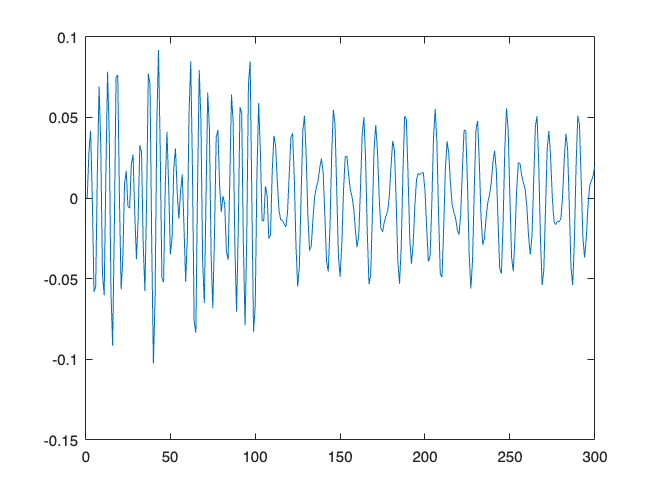

ans = 0

dtmfscore(singleTone, hh(:,6))


% We needed to make sure that all BDF's had the same magnitude = 1 so that we can fairly compare which tones are present in the signal. Since we know
% the amplitude of the input sinusoids (amplitude of 1 each) and we know the gain of each filter (1), we can predict and control the output and
% clearly detect if a tone is present.

